# Data Preprocess

**file**: data_rat010_0704.mat

**class**: well trained day

**Success rate**:

                   press low       press high    omission

cue low        127/134         3                   2

cue high       8                   126/142         5

total press    322               192

**Selected M1's MI**: 0.03~0.01 **TimeDelay**: 0 (5 neuron), 500ms (2), 150ms (1)

***mPFC selection not finished***: 可以看到有delay；MI衰减的很快，很明显只有少数的前几个很重要；MI似乎绝对值很大！firing rate看起来有些像，但没有那么像。

                                                   delay和MI的现象需要和critical day对比后下结论

load data

close all;clear;clc;
[M1, mPFC, ratios, eventTrain, M1num, mPFCnum, actTrain, segTrain, segRatios] = spikeTime2Train("data_rat010_0704.mat");

remove response time too long

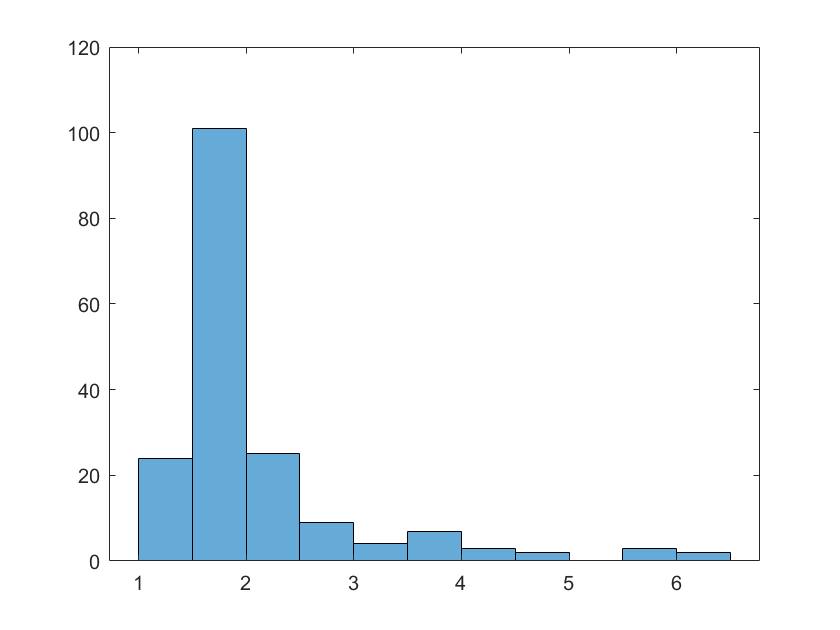

successCount = 0;
spikeLength = length(eventTrain);
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;
histogram(responseTime)

response time大于5s的不要了

trailTooLong = find(responseTime>5);
eventTrainRow = eventTrain;
trailNum = 0;
for i=2:spikeLength
  if (eventTrainRow(i-1) == 0 && eventTrainRow(i) == 1)
    trailNum = trailNum + 1;
  end
  if (eventTrainRow(i) == 1 && ismember(trailNum, trailTooLong))
    eventTrain(i) = 0;
    segTrain(i) = 0;
  end
end

展示success trial

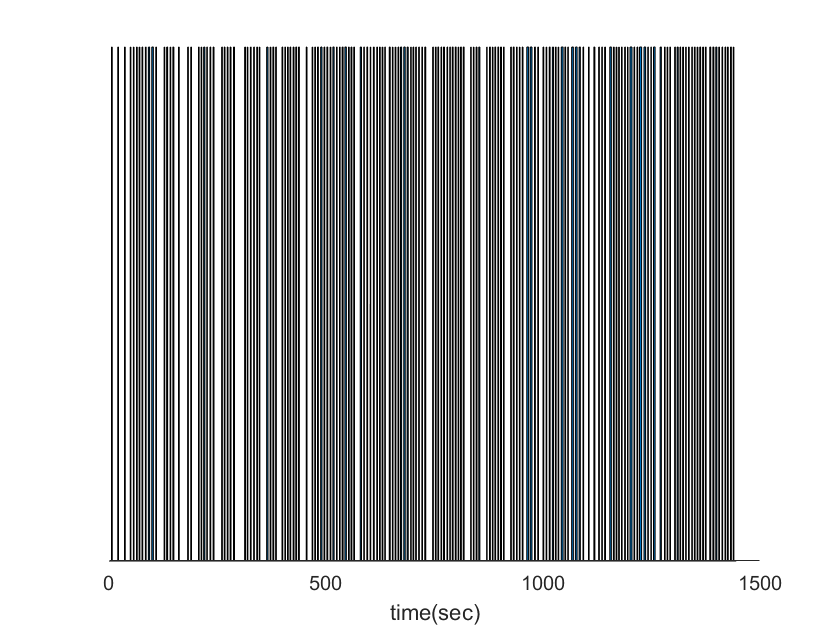

spikeLength = length(eventTrain);
figure
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")

截取一段计算mutual information

takenBins = 20000:144100;
eventTrainPart = eventTrain(takenBins)';
actTrainPart = actTrain(takenBins)';
mPFCPart = mPFC(takenBins,:);
M1Part = M1(takenBins,:);

M1delayMI   = zeros(M1num, 91);
startIdx = -20;
for delay=startIdx:70 % delay vary from -200ms~700ms
    for n=1:M1num
         M1delayMI(n,delay+1-startIdx) = MIcontinuous(gaussianSmooth(M1Part(1-startIdx:end-delay+startIdx,n), 2), gaussianSmooth(actTrainPart(delay+1-startIdx:end+startIdx), 2)); 
    end
end

展示结果

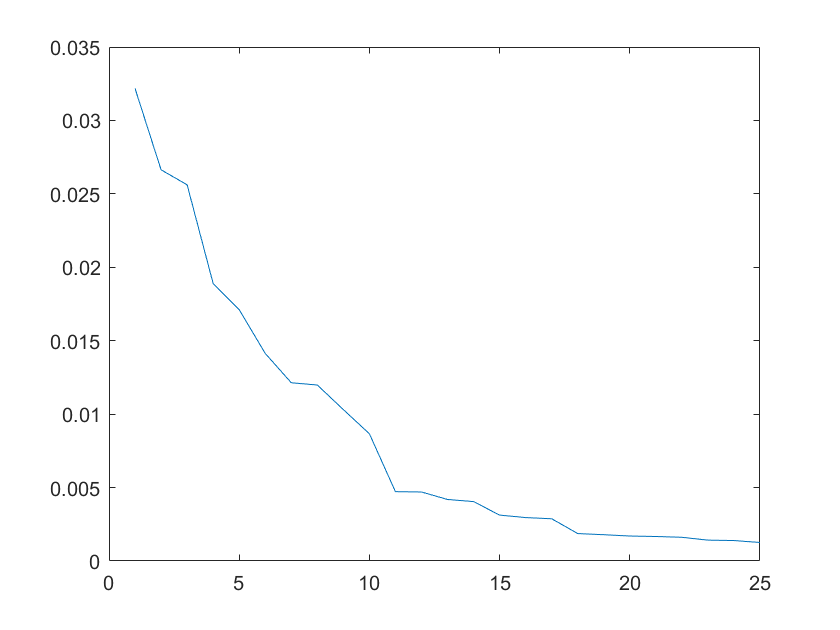

[M1maxMI, M1delay] = max(M1delayMI(:,21:72), [], 2); % reasonable delay should be within 0~200ms
M1maxMI(21) = M1delayMI(21,21+16);
M1delay(21) = 17; % special for this neuron
[MIsorted,I] = sort(M1maxMI, "descend");
plot(MIsorted)

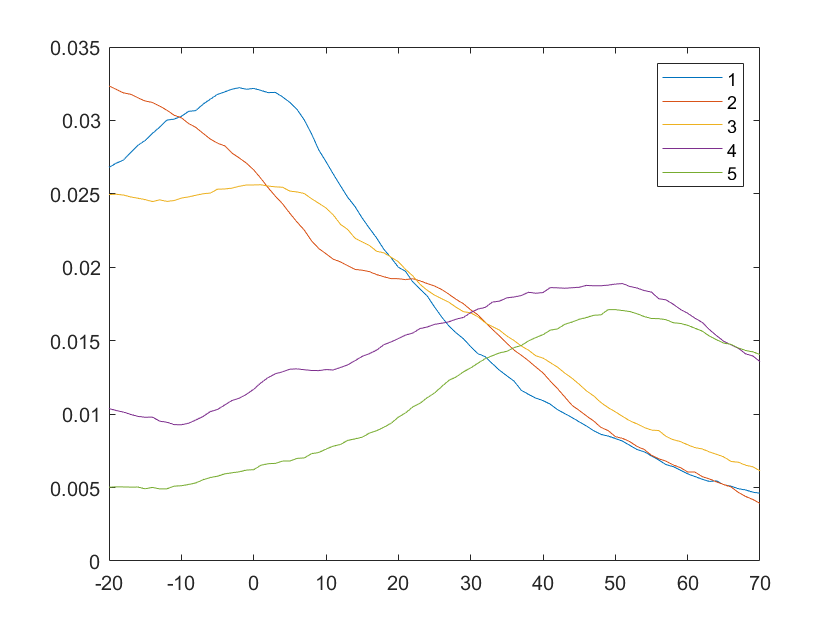

plot(-20:70,M1delayMI(I(1:5),:)')
legend(num2str([1 2 3 4 5]'))

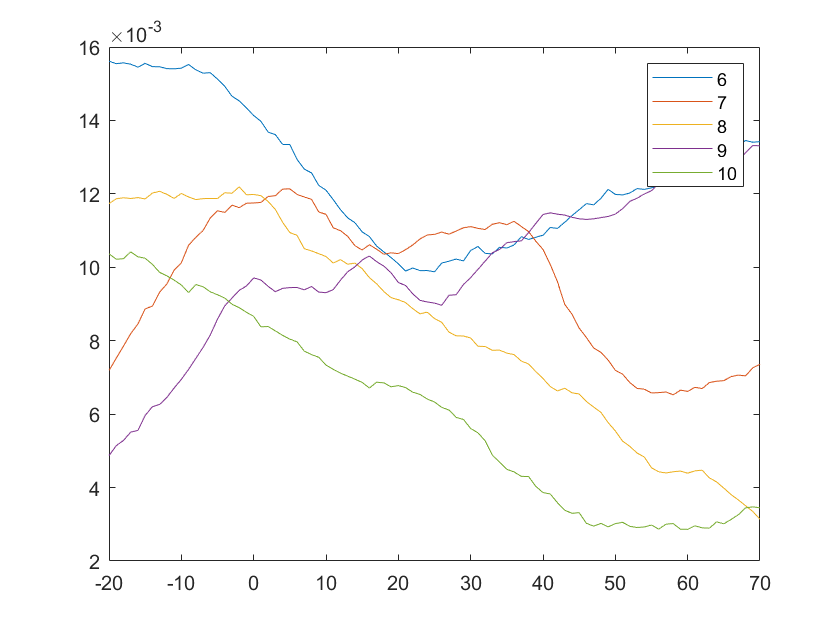

plot(-20:70,M1delayMI(I(6:10),:)')
legend('6','7','8', '9', '10')

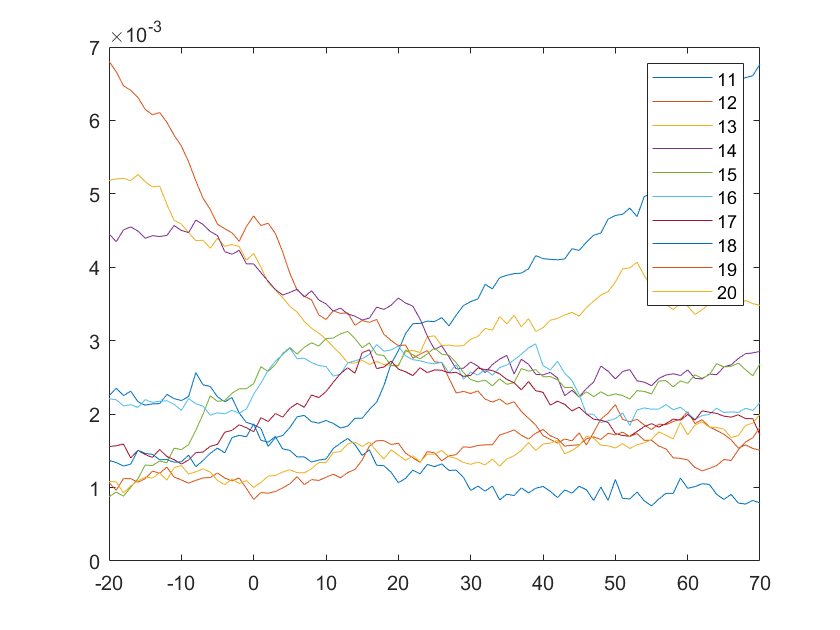

plot(-20:70,M1delayMI(I(11:20),:)')
legend(num2str([11 12 13 14 15 16 17 18 19 20]'))

可以取前8个M1neuron

M1Index = I(1:9);
M1delay = M1delay(I(1:9))-1;

计算M1和mPFC之间

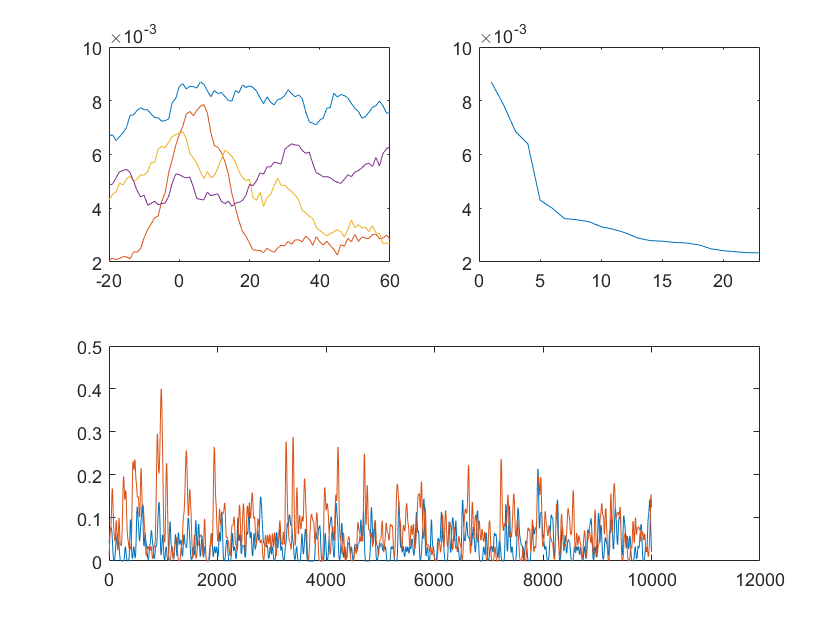

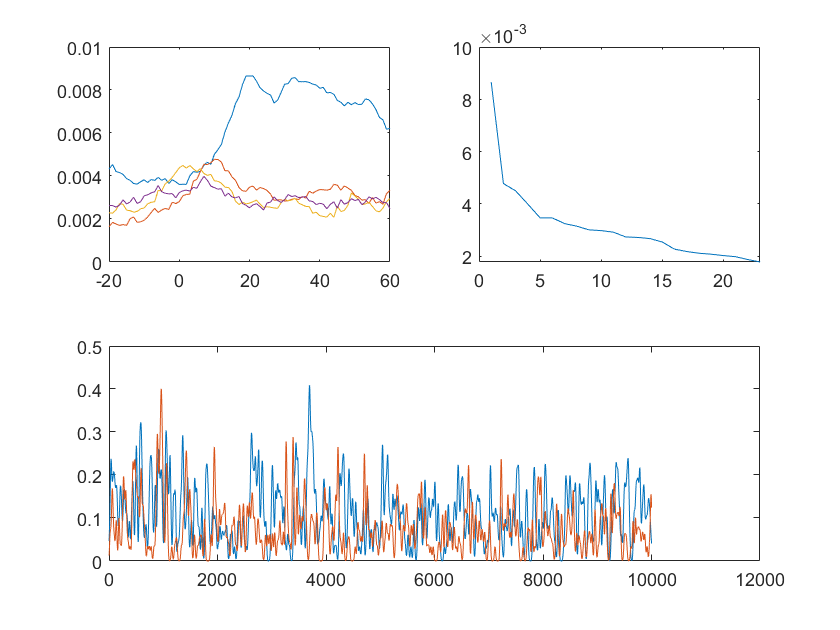

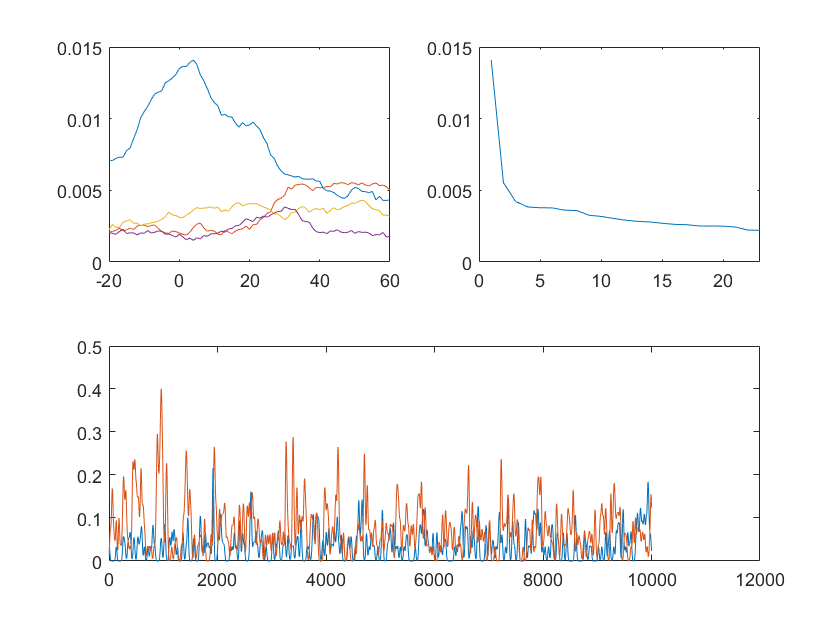

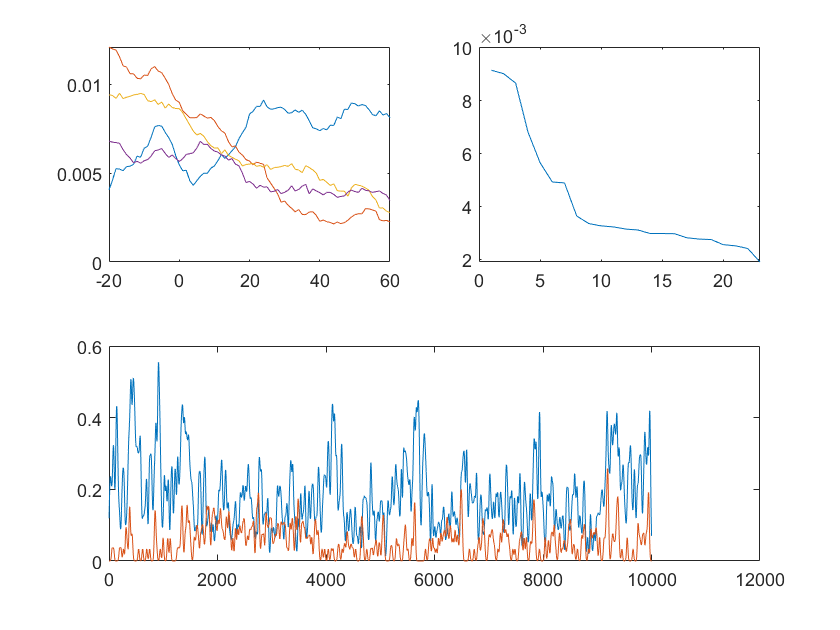

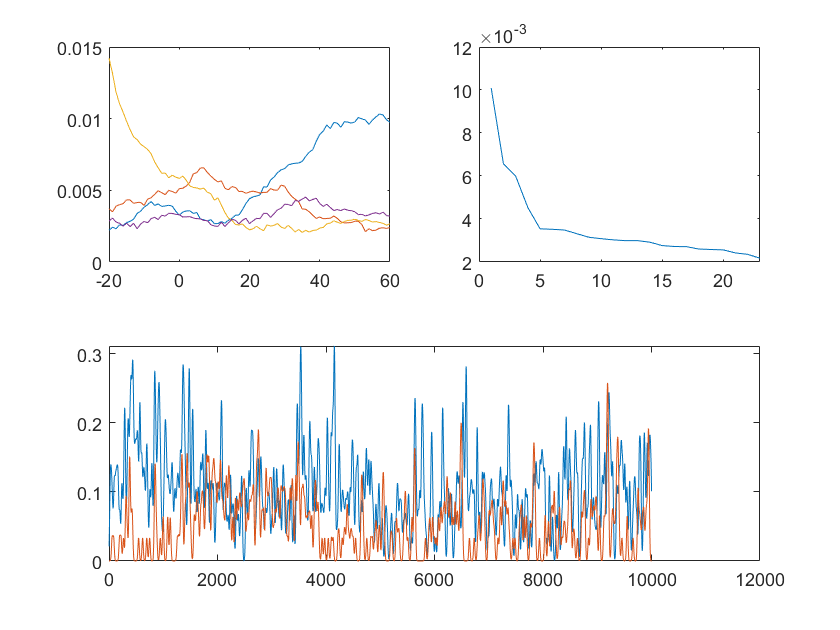

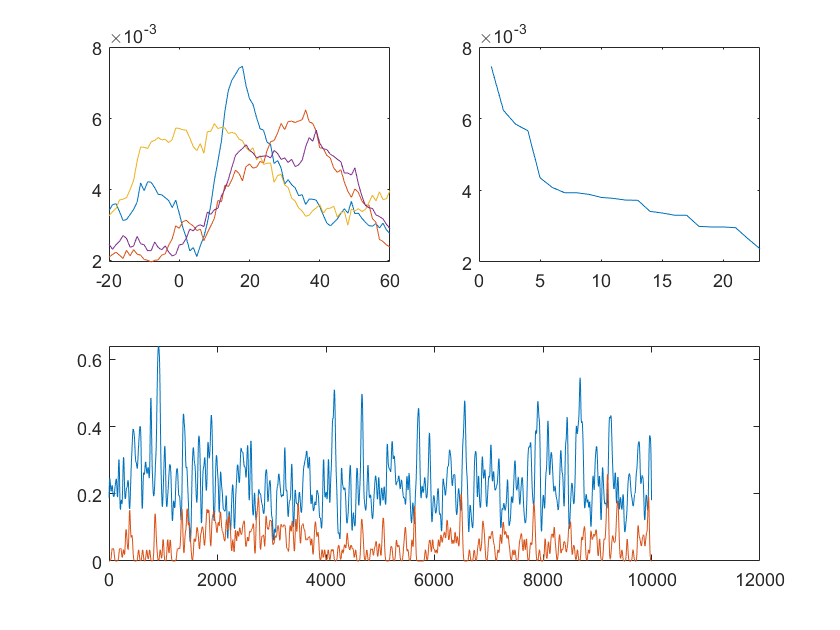

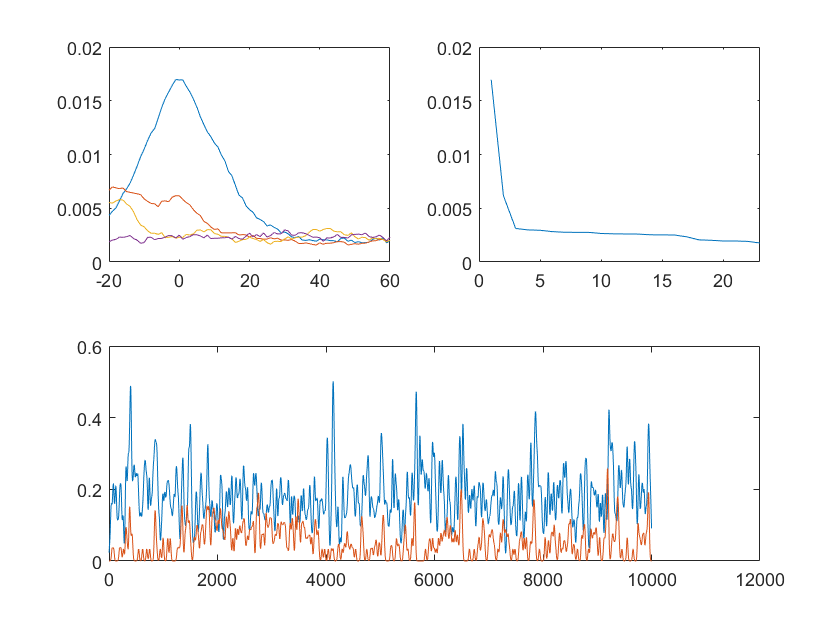

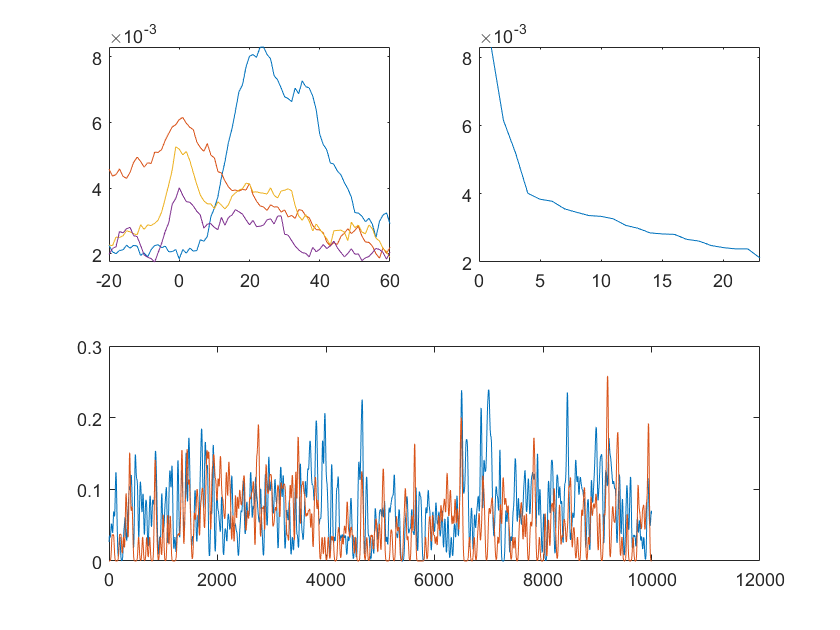

mPFCdelayMI = zeros(9, mPFCnum, 81);
startIdx = -20;
for i=1:9
  for m=1:mPFCnum
    for delay=startIdx:60
      mPFCdelayMI(i, m,delay+1-startIdx) = MIcontinuous(gaussianSmooth(mPFCPart(1-startIdx:end-delay+startIdx,m), 2), gaussianSmooth(M1Part(delay+1-startIdx:end+startIdx,M1Index(i)), 2));
    end
  end
  mPFCmaxMI = max(squeeze(mPFCdelayMI(i,:,21:72)), [], 2);
  [mPFCmaxMISorted,I] = sort(mPFCmaxMI, "descend");
  figure
  subplot(2,2,1)
  plot(-20:60,squeeze(mPFCdelayMI(i, I(1:4),:))')
  subplot(2,2,2)
  plot(mPFCmaxMISorted)
  
  [~,I] = max(mPFCmaxMI);
  subplot(2,1,2)
  plot(gaussianSmooth(M1Part(10000:20000,i), 12))
  hold on
  plot(gaussianSmooth(mPFCPart(10000:20000,I), 12))
  hold off
end